init_turtlebot_connection("10.42.0.1", "10.42.0.28")

Error using init_turtlebot_connection (line 9)
The global ROS node is already initialized and connected to the master at URI "http://10.42.0.1:11311". If you want to restart the global node, call "rosshutdown" first.

map = makemap()

start = [80,100];
goal = [40,40];

bug = Bug2(map);
bug.goal = goal;
bug.verbose = 1;
bug.query(start,goal,'animate')

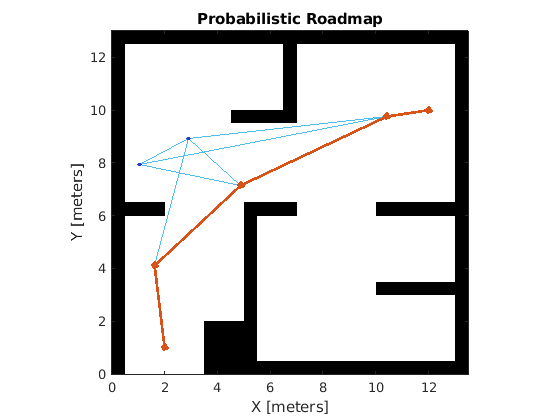

load exampleMaps.mat
map = binaryOccupancyMap(simpleMap,2);

prmComplex = mobileRobotPRM(map,5);

startLocation = [2 1];
endLocation = [12 10];

prmComplex.ConnectionDistance = 10;
path = findpath(prmComplex, startLocation, endLocation);
show(prmComplex)